# Parameters


mMoon =7.348e22;% kg
mEarth = 5.9742e24; %kg
mu = mMoon/(mMoon + mEarth);

k = 50

k = 50

periodo = 3.7837

periodo = 3.7837

## Unstable Manifold

X0 = [0.786717447531649 0 0 0.424560784056642]

X0 =     0.7867         0         0    0.4246


C1 = jacobiConstant([0.786717447531649 0],[0 0.424560784056642],mu)

C1 = 3.0326

STM = reshape(eye(4),16,[])';
Xunstable = [X0 STM]';
epsilon=1e-6;
X_mainfold_unstable = calculateUnStableMainfold(periodo,Xunstable,mu,k,epsilon,false);


## stable manifold

X0 = [1.217882160300000 0 0 -0.420449270532713];
C1 = jacobiConstant([1.217882160300000 0],[0 -0.420449270532713],mu)

C1 = 3.0183

STM = reshape(eye(4),16,[])';
Xstable = [X0 STM]';
X_mainfold_stable = calculateStableMainfold(periodo,Xstable,mu,k,epsilon,false);


## Calculate Poincare map

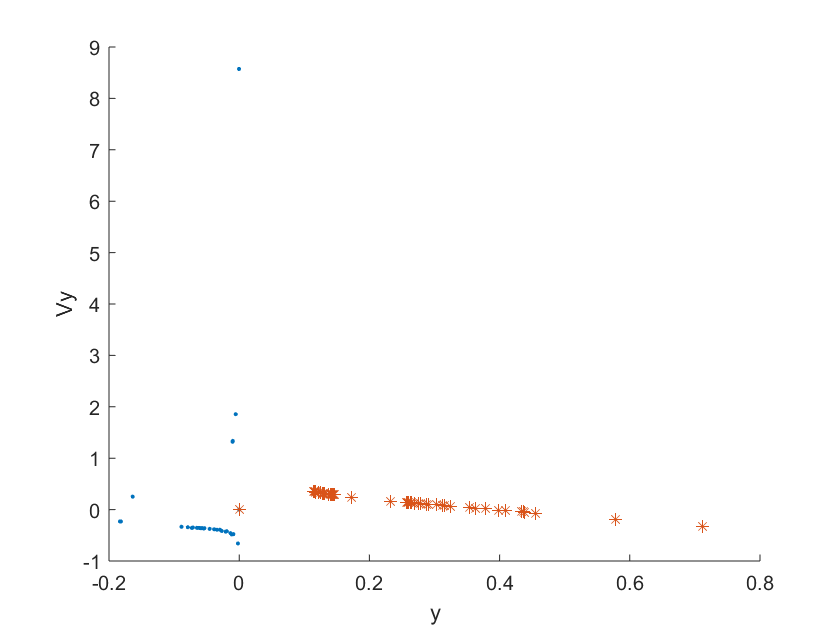


[U2,U3] = callPoincareMap(X_mainfold_unstable,X_mainfold_stable,mu,k,periodo*4);